clearvars;
close all;
clc;

## READ FILE

fileName = uigetfile('*.csv', 'Pilih file CSV yang berisi data training');
file = csvread(fileName);
[X, Y] = size(file);

c = cvpartition(X,"HoldOut", 0.2);
idxTrain = training(c);
train = file(idxTrain, :);
idxVal = test(c);
Val = file(idxVal, :);

XTrain = train(:, 2:Y);
YTrain = categorical(train(:, 1));
XVal = Val(:, 2:Y);
YVal = categorical(Val(:, 1));

numFeatures = size(XTrain, 2);
numClasses = 2;

## SETUP NEURAL NETWORK LAYERS

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       43.75% |       46.67% |       1.0047 |       0.9778 |          0.0010 |
|       5 |          30 |       00:00:09 |       68.75% |       70.00% |       0.5508 |       0.6139 |          0.0010 |
|       8 |          50 |       00:00:10 |       87.50% |              |       0.2161 |              |          0.0010 |
|       9 |          60 |       00:00:11 |       87.50% |       70.00% |       0.3326 |       0.6755 |          0.0010 |
|      1

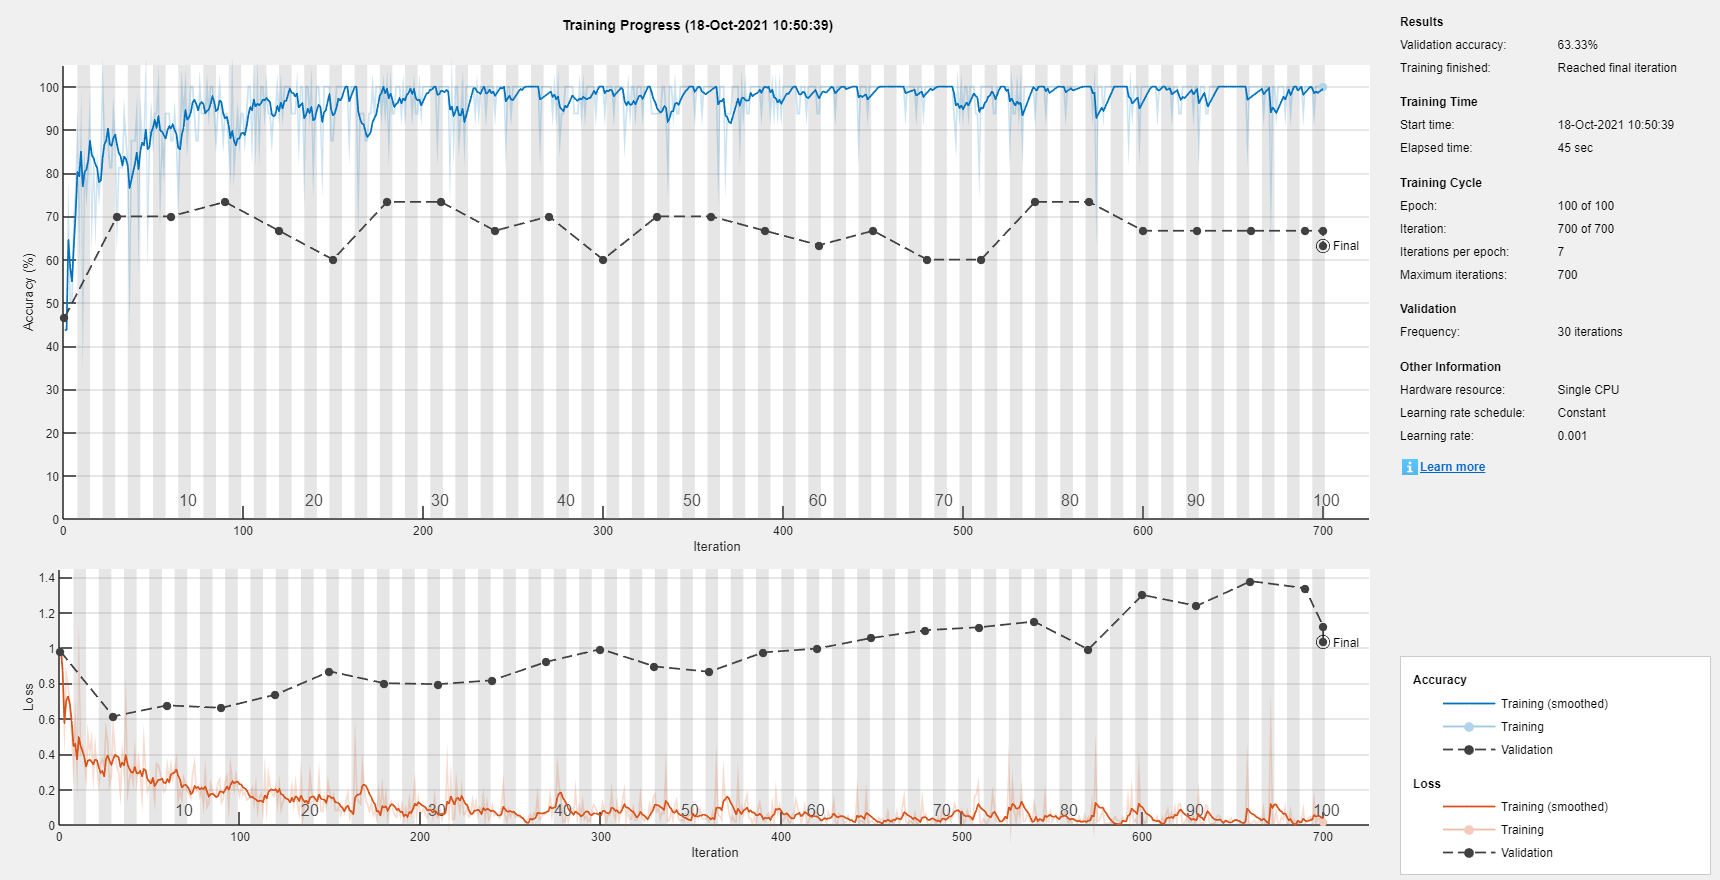

layers = [
    %input layer (480 Total Features)
    featureInputLayer(numFeatures)
    %hidden layer 1 (100 Neurons)
    fullyConnectedLayer(240)
    batchNormalizationLayer
    reluLayer
    %hidden layer 2 (50 Neurons)
    fullyConnectedLayer(50)
    batchNormalizationLayer
    reluLayer
    %hidden layer 3 (50 Neurons)
%     fullyConnectedLayer(50)
%     batchNormalizationLayer
%     reluLayer
    %output neurons (Sesuai Jumlah Class : 2 Neurons)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

miniBatchSize = 16;

options = trainingOptions(...
    'adam', ... %Optimizer Function
    'MaxEpochs',100, ... %Training Cycle
    'MiniBatchSize',miniBatchSize, ... %Processed data per run
    'Shuffle','every-epoch', ... %Randomize data order every epoch
    'Plots','training-progress', ... %Display training progress window
    'Verbose',1, ... %Display Result on command window
    'ValidationData', {XVal,YVal}, ... %Data to use for validation during training
    'ValidationFrequency',30 ... %Frequency of network validation
    );

[net, info] = trainNetwork(XTrain,YTrain,layers,options);

validation_Accuracy = info.FinalValidationAccuracy

validation_Accuracy = 63.3333

validation_Loss = info.FinalValidationLoss

validation_Loss = single
1.0349

network = net;
save('network.mat', 'network');